# Analog Communication Systems

# ***Fourier Series And Transforms***

## Clearing the workspace

close all;
clear;
clc;

## 1. Introduction to DFT and FFT (applicable approach)

In MATLAB both frequency and time axis are discrete. So we should use an operation that is applicable to discrete signals. Just fourier series of discrete signals has this property.

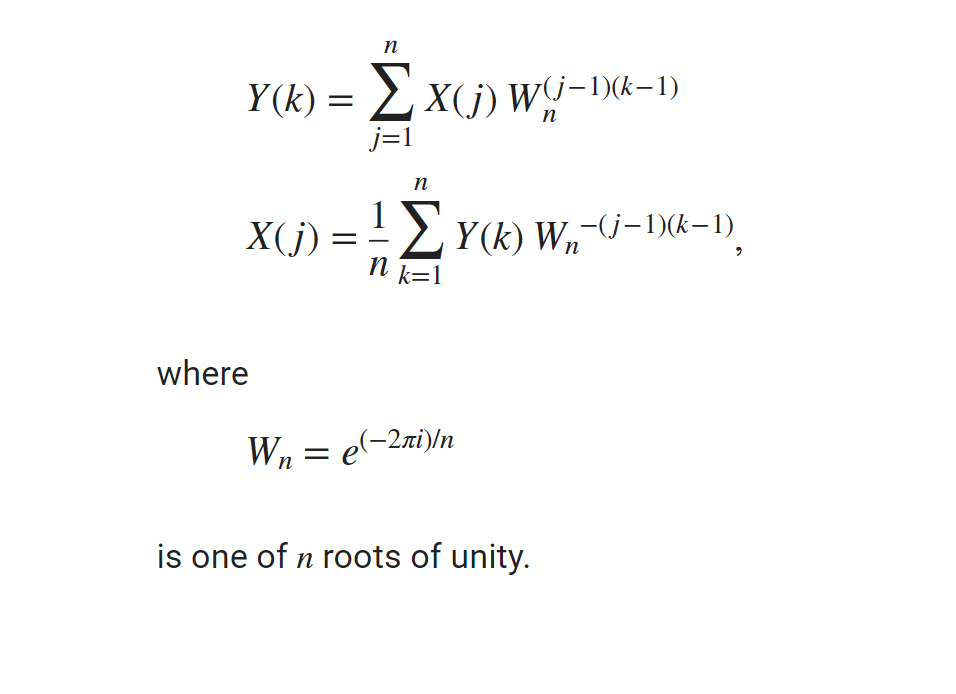

imshow("./images/DFT_MATLAB.png");

## 2. Fourier Series of Discrete Time Signals

### Defining the variables

N = 1e1;
n = -N:N;
N0 = 5;
M0 = 3;
w0 = 2 * pi / N0;
w = M0 * w0;

### Defining and plotting the signal

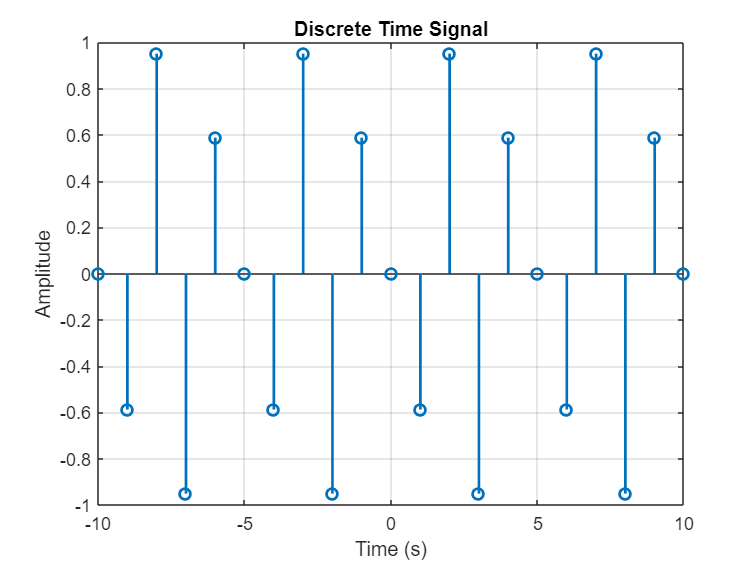

x = sin(w * n);

figure('Name', 'Discrete Time Signal');
stem(n, x, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Discrete Time Signal');
grid on;

### Calculating and plotting the Fourier series

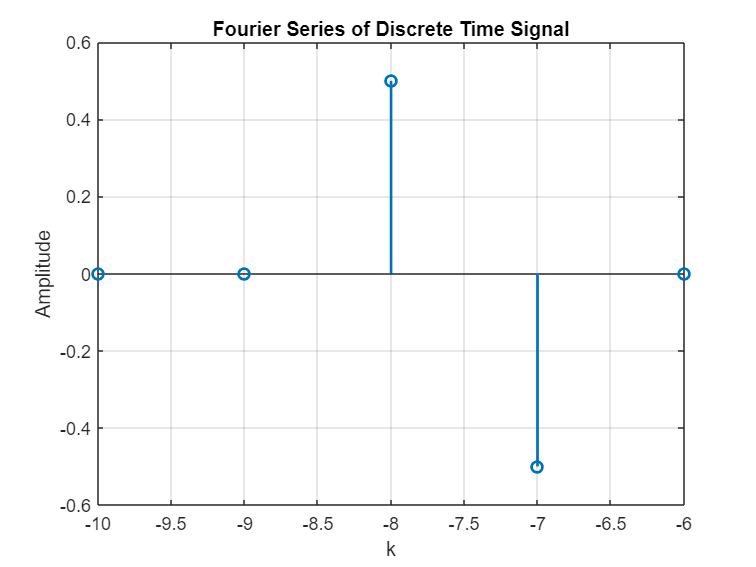

a_k = fft(x(1:N0)) / N0;
k = n(1:N0);
figure('Name', 'Fourier Series of Discrete Time Signal');
stem(k, imag(a_k), 'LineWidth', 1.5);
xlabel('k');
ylabel('Amplitude');
title('Fourier Series of Discrete Time Signal');
grid on;

### Reconstructing the signal from the Fourier series

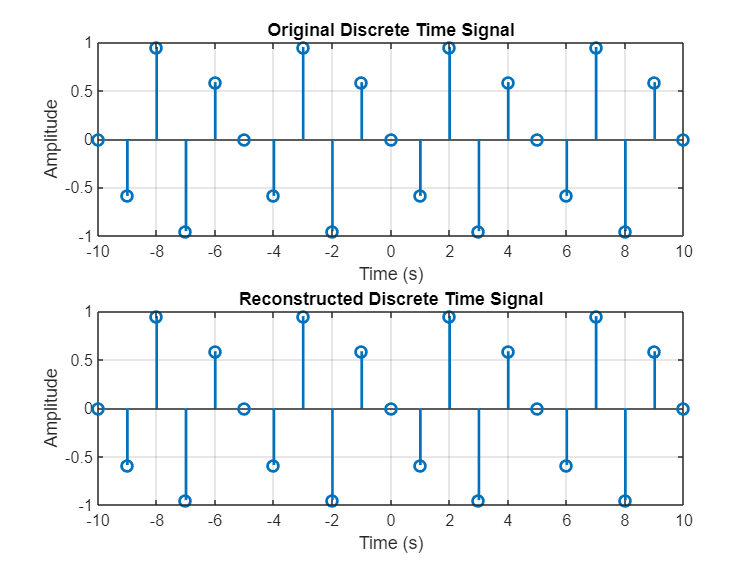

kernel = exp(1j * w0 * k' * n);
x_reconstructed = a_k * kernel;

figure('Name', 'Reconstructed Discrete Time Signal');
subplot(2, 1, 1);
stem(n, x, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Discrete Time Signal');
grid on;
subplot(2, 1, 2);
stem(n, real(x_reconstructed), 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Reconstructed Discrete Time Signal');
grid on;

## 3. Fourier Transform of Discrete Time Signals (DTFT)

The Fourier transform of a discrete time signal is a periodic signal with the period of $2\pi$. The Fourier transform of a discrete time signal is defined in the interval $-\pi$ to $\pi$.

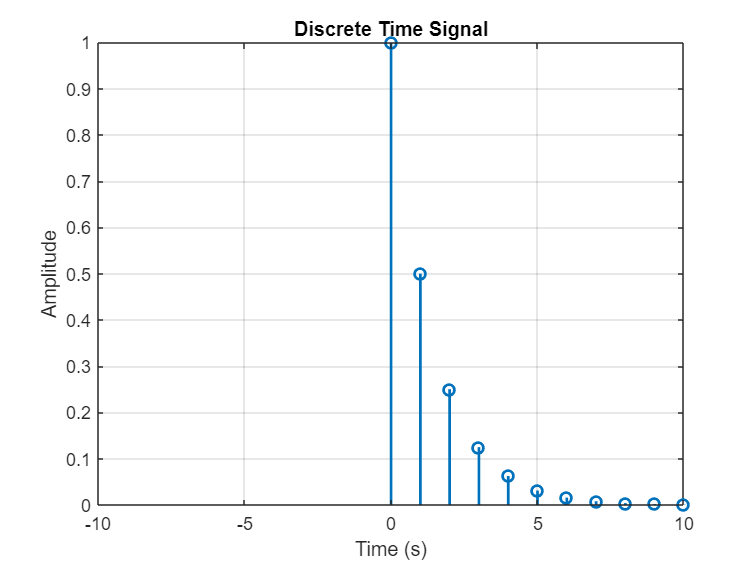

N = 1e3;
n = 0:N;
a = 0.5;
x = a.^n;

figure('Name', 'Discrete Time Signal');
stem(n, x, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Discrete Time Signal');
grid on;
xlim([-10, 10]);

### Calculating and plotting the Discrete Time Fourier Transform of the signal

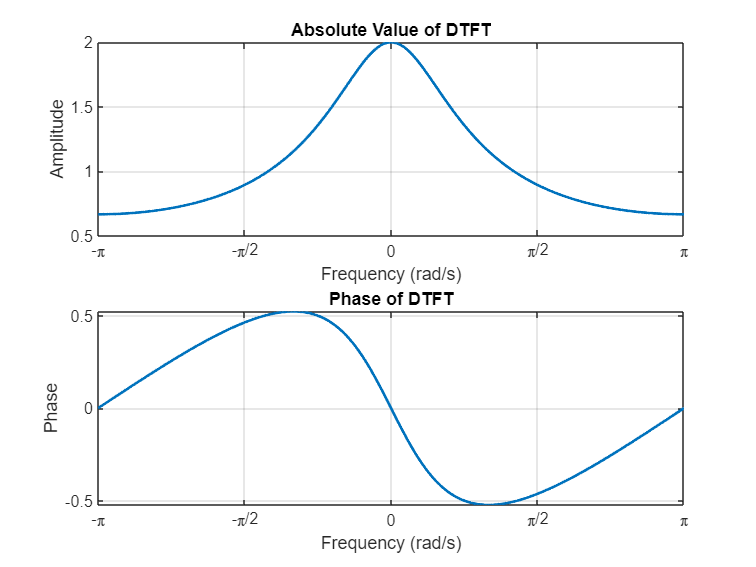

w_axis = linspace(-pi, pi, 1e3);
DTFT_x = x * exp(-1j * n' * w_axis);

figure('Name', 'DTFT of Discrete Time Signal');
subplot(2, 1, 1);
plot(w_axis, abs(DTFT_x), 'LineWidth', 1.5);
xlabel('Frequency (rad/s)');
ylabel('Amplitude');
title('Absolute Value of DTFT');
xlim([-pi pi]);
xticks([-pi, -pi / 2, 0, pi / 2, pi]);
xticklabels({'-\pi', '-\pi/2', '0', '\pi/2', '\pi'});
grid on;

subplot(2, 1, 2);
plot(w_axis, angle(DTFT_x), 'LineWidth', 1.5);
xlabel('Frequency (rad/s)');
ylabel('Phase');
xlim([-pi pi]);
xticks([-pi, -pi / 2, 0, pi / 2, pi]);
xticklabels({'-\pi', '-\pi/2', '0', '\pi/2', '\pi'});
title('Phase of DTFT');
grid on;

## 4. Fourier Transform of Continuous Time Signals

Considerations: 

- Both positive and negative part of time axis should be considered. 

- Nyquist theorem should be considered.

- The main part of the signal should be included in the time axis. (For periodic signals, the main part is the period of the signal.)

Increasing the number of samples $\rightarrow$ Detecting higher frequencies

Increasing time axis interval $\rightarrow$ higher frequency resolution

The amplitude of the frequency spectrum is not that important.

Period of the lowest non-zero frequency $\to$ Interval of time axis

Total number of frequency spectrum samples $\to$Total number of time domain samples

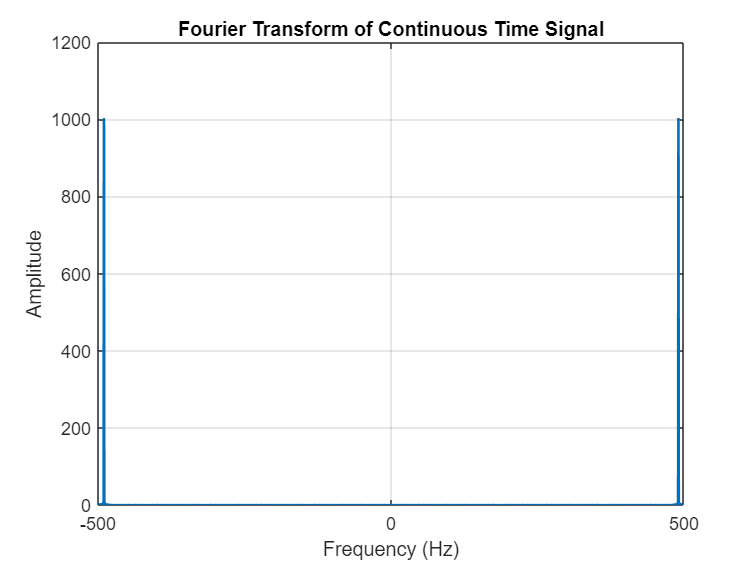

fs = 1e3;
t = -1:1 / fs:1;
f0 = 10;
x = cos(2 * pi * f0 * t);

FT_x = fft(x);
f_axis = linspace(-fs / 2, fs / 2, length(FT_x));

figure('Name', 'Fourier Transform of Continuous Time Signal');
plot(f_axis, abs(FT_x), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Fourier Transform of Continuous Time Signal');
grid on;

- FFT formula  in matlab is not the same as the definition of fft formula; FFT formula is the same as the definition of fftshift. So we should use fftshift to shift the frequency axis to the center.

- DFT of a signal is a periodic signal with the period of $f_s$.

- fft function in matlab calculates the fft in the interval 0 to fs.

- fftshift function calculates the fft in the interval -fs / 2 to fs / 2.

For more accurate results, we should use a longer time axis:

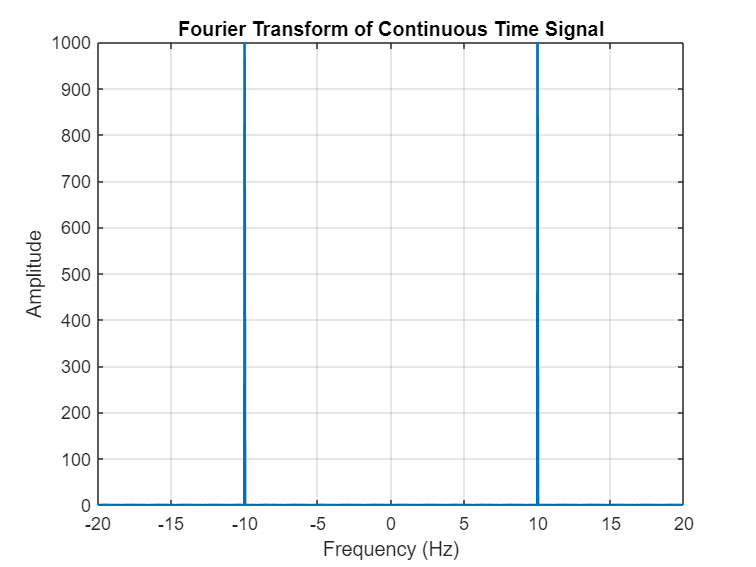

fs = 1e3;
N = 1e3;
t = -N:1 / fs:N;
f0 = 10;
x = cos(2 * pi * f0 * t);

FT_x = (1 / fs) * fftshift(fft(x));
f_axis = linspace(-fs / 2, fs / 2, length(FT_x));

figure('Name', 'Fourier Transform of Continuous Time Signal');
plot(f_axis, abs(FT_x), 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Fourier Transform of Continuous Time Signal');
xlim([-20, 20]);
grid on;

**Question:** Why the delta function in frequency have different maximum value?

## 5. Fourier Series of Continuous Time Signals

`1(Sec.) `$\to$` fs(Samples)`

`T0(Sec.) `$\to$` T0 * fs(Samples)`

- For more terms of Fourier series, we should increase the sampling frequency to extend the terms of fft output.

- To maximize the number of FS terms, we should take N equal with half of the number of fft terms; But at this number, the nyquist theorem is not agreed. So we should take N, in a way that the number of samples is more than the twice of bandwidth or we should take N as the maximum and define a new axis for the reconstructed signal with fs_new  =  2 * fs_old. The second way is better.

- The ration of Nyquist boundary is maximum at 1/2.

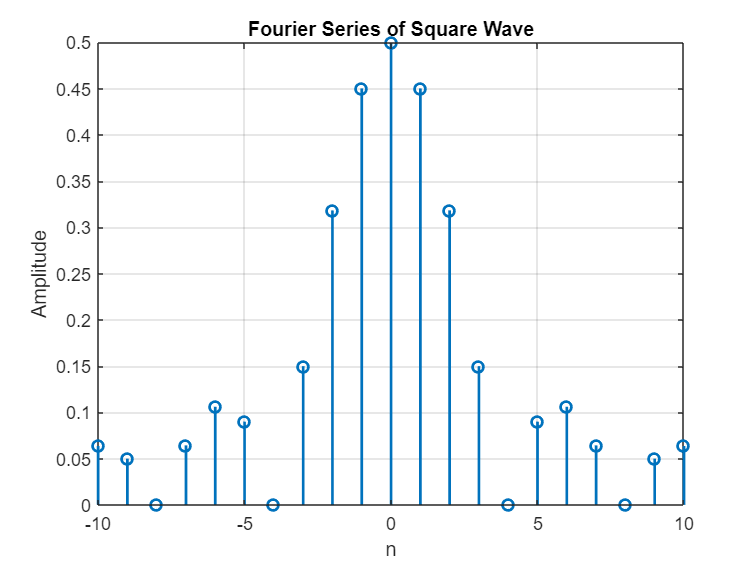

fs = 1e4;
T_eq = 1;
t = -T_eq:1 / fs:T_eq;
T0 = 0.5;
duty_cycle = 0.25;
square_wave = square(2 * pi * t / T0, duty_cycle * 100);

FT_square_wave = fftshift(fft(square_wave(1:fs * T0))) / (fs * T0);

m0 = 1 + floor((fs * T0) / 2);
ratio_Nyq_boundary = 1/2;
N = floor(T0*fs*ratio_Nyq_boundary) - 1;
a_n = FT_square_wave(m0 - N:m0 + N);
n = -N:N;
figure('Name', 'Fourier Series of Square Wave');
stem(n, abs(a_n), 'LineWidth', 1.5);
xlabel('n');
ylabel('Amplitude');
title('Fourier Series of Square Wave');
xlim([-10 10]);
grid on;

### Reconstructing the square wave from the Fourier series

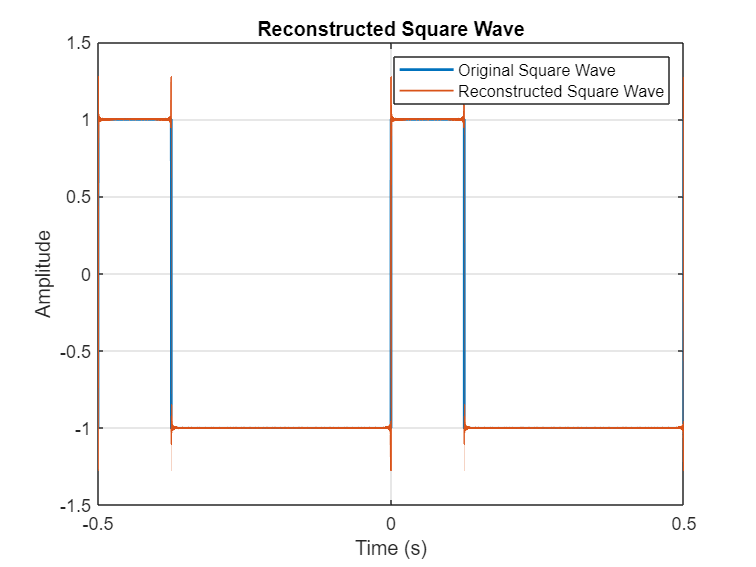

t1 = -1:1/(2*fs):1;
kernel = exp(1j * 2 * pi * n' * t1 / T0);
x = a_n * kernel;

figure('Name', 'Reconstructed Square Wave');
plot(t, square_wave, 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Reconstructed Square Wave');
grid on;
hold on;
plot(t1, real(x), 'LineWidth', 1);
legend('Original Square Wave', 'Reconstructed Square Wave');
xlim([-0.5, 0.5]);